# **Práctica 6: Series de Fourier en tiempo continuo**

## Integtrantes

- **Juan Manuel Bautista Uribe**

- **David Joshua Aquino Soto**

- **Fernanda Itzel Bernabe Baez**

- **Luis Enrique Salazar Fuentes**

## **Objetivos**

- Realizar gráficas de series de Fourier exponenciales y trigonométricas en tiempo continuo

- Manipulación de instrucciones en MATLAB

## PR08-1

Serie exponencial

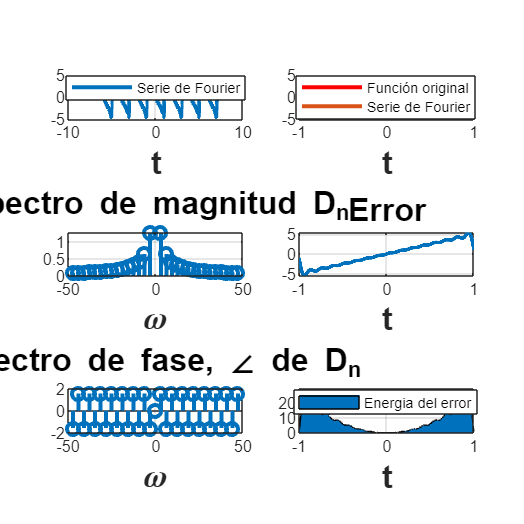

d0=0;
dn=@(n) 4*(-1)^n/(pi*n*j);
t0=-1;
tf=1;
f=@(t) t;
armo=15;
a=-7;
b=7;
sfc(t0,tf,dn,d0,f,armo,a,b)

## PR08-2

Serie exponencial

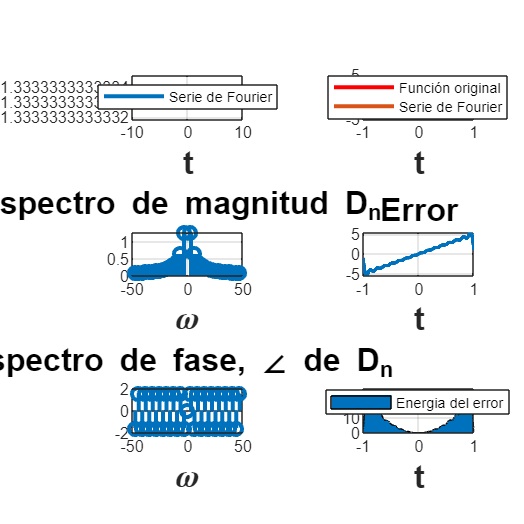

Error using  ^ 
Incorrect dimensions for raising a matrix to a power. Check that the matrix is square and the power is a scalar. To
operate on each element of the matrix individually, use POWER (.^) for elementwise power.

Error in Practica_6 (line 14)
f=@(t) t^2;

Error in sfc (line 34)
plot(t1,f(t1),'r','LineWidth',2)

d0= 4/3;
dn=@(n) 32*(-1)^n/(pi^2*n^2*j);
t0=-2;
tf=2;
f=@(t) t^2;
armo=15;
a=-10;
b=10;
sfc(t0,tf,dn,d0,f,armo,a,b)

### Apendice

function sfc(t0,tf,dn,d0,f,armo,a,b)
% t0 el valor inicial para calcular la serie
% tf el valor final donde calcular la serie
% dn función de la fórmula de los dn
% f función original
% armo número de armonicos a utilizar en la gráfica
% a, b intevalo para realizar la grafica de la serie

w0=2*pi/(tf-t0);

sf=d0;
t=a:0.0001:b;

for n=1:armo
    sf=sf+dn(-n)*exp(w0*-n*t*j)+dn(n)*exp(w0*n*t*j);
end
figure (1)
hFig = figure(1);
set(hFig, 'Position', [0 0 900 900])
subplot(3,2,1)
plot(t,sf,'LineWidth',2)
grid on
legend('Serie de Fourier','Location','Best')
xlabel('t','FontWeight','bold','FontSize',16)

sf=d0;
t1=t0:0.0001:tf;

for n=1:armo
    sf=sf+dn(-n)*exp(w0*-n*t1*j)+dn(n)*exp(w0*n*t1*j);
end

subplot(3,2,2)
plot(t1,f(t1),'r','LineWidth',2)
grid on
hold on
plot(t1,sf,'LineWidth',2)
legend('Función original','Serie de Fourier ','Location','Best')
xlabel('t','FontWeight','bold','FontSize',16)
nn=-armo:armo;
axis auto

subplot(3,2,4)
e=f(t1)-sf;
plot(t1,e,'LineWidth',2)
title('Error','FontWeight','bold','FontSize',16)
xlabel('t','FontWeight','bold','FontSize',16)
axis auto
grid on

subplot(3,2,6)
e=f(t1)-sf;
area(t1,e.^2)
legend('Energia del error','Location','Best')
xlabel('t','FontWeight','bold','FontSize',16)
axis auto
grid on

absdn=zeros(1,length(nn));
cont=1;
for i =-armo:armo
    if i==0
        absdn(cont)=d0;
    end
    
    absdn(cont)=dn(i);
    cont=cont+1;
end

subplot(3,2,3)
stem(w0*nn,abs(absdn),'LineWidth',2)
title('Espectro de magnitud D_n ','FontWeight','bold','FontSize',16)
xlabel('\omega','FontWeight','bold','FontSize',16)
grid on

subplot(3,2,5) % % 
stem(w0*nn,angle(absdn),'LineWidth',2) % % 
title('Espectro de fase, \angle de D_n ','FontWeight','bold','FontSize',16) % % 
xlabel('\omega','FontWeight','bold','FontSize',16)
grid on

end